With data is imported from the  **COVID-19 Data Repository by the Center for Systems Science and Engineering (CSSE) at Johns Hopkins University**, two vectors are produced to approximate the values of $\beta \;$and $\nu$. The approximations are functions of time to reflect the counter measures that are being put into place. 

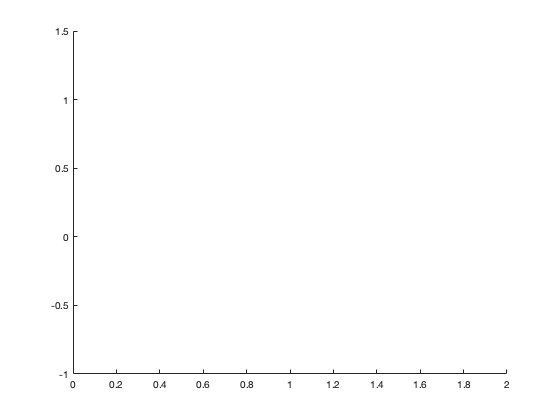

confirmed = loadData('confirmed');
deaths = loadData('deaths');
recovered = loadData('recovered');

region = 12; % Queensland;
t = 12:width(confirmed) ;
w=width(confirmed)-12 ;
qlpop = 5072000; 

s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t};
i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t};
r1 = deaths{region,t} + recovered{region,t};

M = transpose([s1; i1; r1]);

[b, v] = betaVegaCalc(s1, (confirmed{region,t}), (deaths{region,t}), (recovered{region,t}), w, qlpop);
b=.0871*b/b;
figure
hold on
plot(b)

Once the data is sufficiently loaded, a quick plot was used to ensure the complete and accurate data is being used.

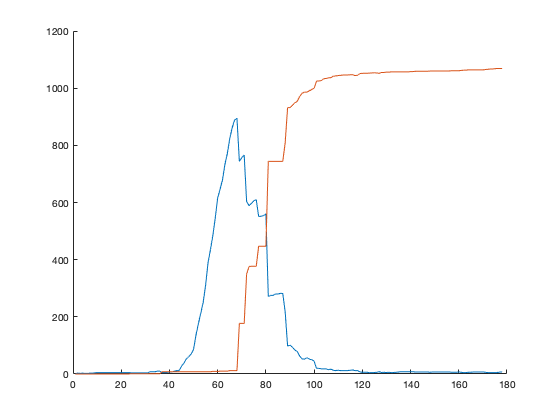

figure
hold on
plot(confirmed{region,t}-deaths{region,t}-recovered{region,t})
plot(deaths{region,t}+recovered{region,t})

[pks, locs] = findpeaks(confirmed{region,t}-deaths{region,t}-recovered{region,t})

pks =      3     3     5    10   895   766   610   560   282   101    57    17    13    14     8     6     6     8     7     7     7


locs =      2     4    10    35    68    71    76    80    86    90    97   107   110   116   127   129   131   136   149   160   166


In order to calculate $R_0$, the Jacobian matrix representing the rates of change amongst all the comparments (Susceptible, Infected, and Recovered) are calculated. Epidimiologist utilized this matrix to determine the rate of change produced by a single infected individual; this is accomplished by utilized the eigenvalues. The spectrul radius, or dominant eigenvalue, ends up becoming the rate of infection from a single infection.

br = 0;

u = 1 - v;
t=50;

s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t};
i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t};
r1 = deaths{region,t} + recovered{region,t};

% Pretending Birth Rate and Death Rate do not apply.
J = [-b*i1/qlpop -b*s1/qlpop 0; b*i1/qlpop b*(s1/qlpop)-v(t) 0; 0 v(t) 0]

J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


%Birth Rate and Death Rate Apply
%J = [-b(t)*i1-u(t) -b(t)*s1 0; b(t)*i1 b(t)*s1-v(t)-u(t) 0; 0 v(t) -u(t)];
[V,D] = eig(J);
D

D =    -0.0000         0         0
         0    0.0871         0
         0         0         0


r0=[];
for t = 1:w-1
    J = [-b*i1/qlpop -b*s1/qlpop 0; b*i1/qlpop b*(s1/qlpop)-v(t) 0; 0 v(t) 0]
    [V,D] = eig(J);
    r0 = [r0 max(max(D))];
end

J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000   -0.1129         0
         0    0.2000         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000   -0.6129         0
         0    0.7000         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J =    -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0848         0
         0    0.0023         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0855         0
         0    0.0016         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0845         0
         0    0.0026         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0973         0
         0    0.1844         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.1374         0
         0    0.2245         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0424         0
         0    0.0447         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0854         0
         0    0.0017         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0277         0
         0    0.1148         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.4433         0
         0    0.5304         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.1434         0
         0    0.2305         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.4797         0
         0    0.5668         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0079         0
         0    0.0792         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0086         0
         0    0.0957         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0276         0
         0    0.0595         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.1281         0
         0    0.2152         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0875         0
         0    0.1746         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0116         0
         0    0.0755         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0006         0
         0    0.0877         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0102         0
         0    0.0769         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0129         0
         0    0.1000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.4685         0
         0    0.5556         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0129         0
         0    0.1000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.2462         0
         0    0.3333         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0315         0
         0    0.0556         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0240         0
         0    0.1111         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0204         0
         0    0.0667         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.2070         0
         0    0.2941         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0102         0
         0    0.0769         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0038         0
         0    0.0833         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0102         0
         0    0.0769         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0038         0
         0    0.0833         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0038         0
         0    0.0833         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.3014         0
         0   -0.2143         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0038         0
         0    0.0833         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.4129         0
         0    0.5000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0558         0
         0    0.1429         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0796         0
         0    0.1667         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.1129         0
         0    0.2000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.2871         0
         0   -0.2000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.2538         0
         0   -0.1667         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.2879         0
         0    0.3750         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0796         0
         0    0.1667         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0796         0
         0    0.1667         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0379         0
         0    0.1250         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0379         0
         0    0.1250         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0558         0
         0    0.1429         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0558         0
         0    0.1429         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0558         0
         0    0.1429         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0796         0
         0    0.1667         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.1129         0
         0    0.2000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0558         0
         0    0.1429         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.0796         0
         0    0.1667         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.1129         0
         0    0.2000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.1129         0
         0    0.2000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000   -0.1129         0
         0    0.2000         0


J = 3×3
   -0.0000   -0.0871         0
    0.0000    0.0871         0
         0         0         0


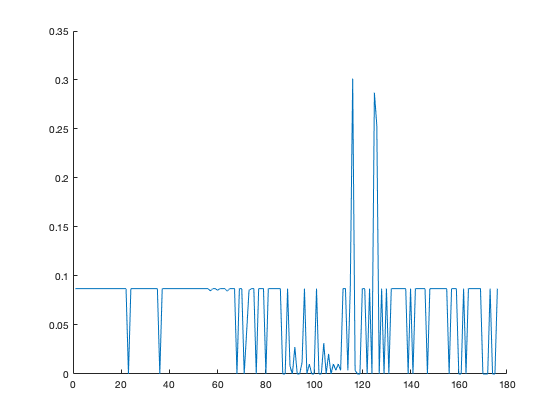

figure
hold on
plot(r0);